## Define the function to integrate

f = @(x) sin(x);
a = 0;
b = pi;
x = linspace(a, b, 1000);
xf = a:(b-a)/n:b;
n = 6; % number of subintervals (even for appliance of Simpson's rule)

## Methods applied

I_trap = trapezoidal_repeated(f, a, b, n);
I_rect = rectangle_repeated(f, a, b, n);
I_simp = simpson_repeated(f, a, b, n);

fprintf('Trapezoidal Rule: %.6f\n', I_trap);

Trapezoidal Rule: 1.954097


fprintf('Midpoint Rule:    %.6f\n', I_rect);

Midpoint Rule:    2.023030


fprintf('Simpson''s Rule:   %.6f\n', I_simp);

Simpson's Rule:   2.000863


## Trapezoidal plotted

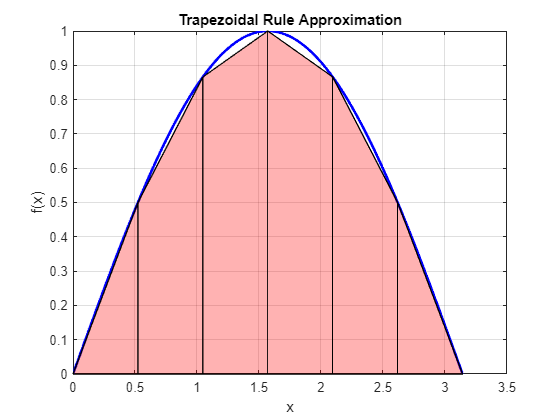

figure;
plot(x, f(x), 'b-', 'LineWidth', 2); hold on;
title('Trapezoidal Rule Approximation');
xlabel('x'); ylabel('f(x)');
grid on;

for i = 1:n
    x1 = xf(i);
    x2 = xf(i+1);
    y1 = f(x1);
    y2 = f(x2);
    fill([x1 x2 x2 x1], [0 0 y2 y1], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'k');
end

## Rectangle plotted

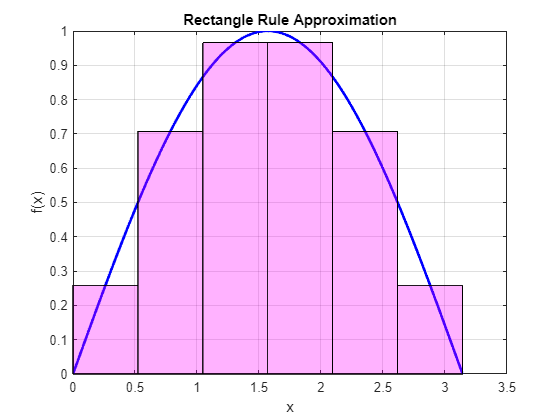

figure;
plot(x, f(x), 'b-', 'LineWidth', 2); hold on;
title('Rectangle Rule Approximation');
xlabel('x'); ylabel('f(x)');
grid on;

h = (b - a) / n;
for i = 1:n
    % Compute the midpoint of the current subinterval
    x_left = a + (i - 1) * h;
    x_right = x_left + h;
    x_mid = (x_left + x_right) / 2;
    
    % Height of rectangle is f(midpoint)
    y_mid = f(x_mid);
    
    % Draw rectangle using fill
    fill([x_left x_right x_right x_left], [0 0 y_mid y_mid], ...
        'm', 'FaceAlpha', 0.3, 'EdgeColor', 'k');
end

## Simpson plotted

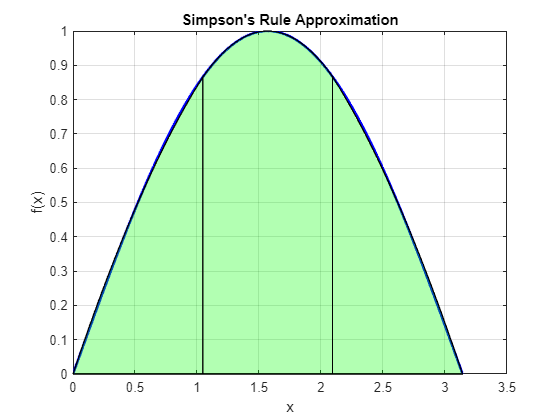

figure;
plot(x, f(x), 'b-', 'LineWidth', 2); hold on;
title('Simpson''s Rule Approximation');
xlabel('x'); ylabel('f(x)');
grid on;

for i = 1:2:n
    x1 = xf(i);
    x2 = xf(i+2);
    x_mid = (x1 + x2) / 2;
    xx = linspace(x1, x2, 100);
    
    % Interpolating quadratic polynomial through x1, x_mid, x2
    X = [x1, x_mid, x2];
    Y = f(X);
    coeffs = polyfit(X, Y, 2);
    yy = polyval(coeffs, xx);
    
    fill([xx fliplr(xx)], [yy zeros(size(yy))], 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'k');
end